
load_from_checkpoint = true;
checkpointLocation = '\\citadel.bio.brandeis.edu\sharespace-commsub/checkpoint.mat'; % path to checkpoint file : so you don't have to rerun this everytime

Run script or load from checkpoint

if ~load_from_checkpoint
    TheScript
else
    load(checkpointLocation)
end

Error using readtable (line 198)
Reference to non-existent field 'text'.

Error in TheScript (line 9)
TABLE = readtable("Megatable.csv");

% if loaded checkpoint.mat
path = strcat( "\\citadel.bio.brandeis.edu\sharespace-commsub\data\", animal)
addpath(path)
path2 = "C:\Users\BrainMaker\MATLAB Drive\Shared"
cd(path2)
addpath(genpath('utils')); % all folders in utils added, including semedo code

Figure 2A: Cofiring in source and target

Figure 2B: Prediction Performance

Figure 4A/B: Results from rank regress

Figure 4C: How optimal number of predicitive dimensions compare between hpc and pfc

## Figure 2

#### A: How pairs of neuron in source/target co-fire

cofiringstats = load("cofiring.mat");
all_pairs_across_regions = [];
all_pairs_within_hpc = [];
for i = 1:nPatterns
    curr_source = X_source{i}';
    curr_HPC = X_target{1,i}';
    curr_PFC = X_target{2,i}';
    
    linearized_hh = plots.calculatePatternCofiring(curr_source, curr_HPC);
    linearized_hp = plots.calculatePatternCofiring(curr_source, curr_PFC);
    
    all_pairs_within_hpc = [all_pairs_within_hpc, linearized_hh];
    all_pairs_across_regions = [all_pairs_across_regions, linearized_hp];
end
figure (500)
subplot(2,1,1)
ax1 = nexttile;
hist_hh = histogram(all_pairs_within_hpc)
ylabel("Pairs")
title ("HPC-HPC")

hist_hh =   Histogram with properties:

             Data: [1×5904 double]
           Values: [12 18 50 92 208 428 638 542 428 386 314 296 270 228 188 170 144 152 94 76 72 88 68 52 44 40 20 18 40 20 22 24 16 26 20 6 10 6 12 0 6 4 8 2 2 0 2 0 2 0 0 0 0 0 0 0 0 0 0 2 0 0 2 0 0 0 0 0 2]
          NumBins: 69
         BinEdges: [1×70 double]
         BinWidth: 0.0100
        BinLimits: [-0.0700 0.6200]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


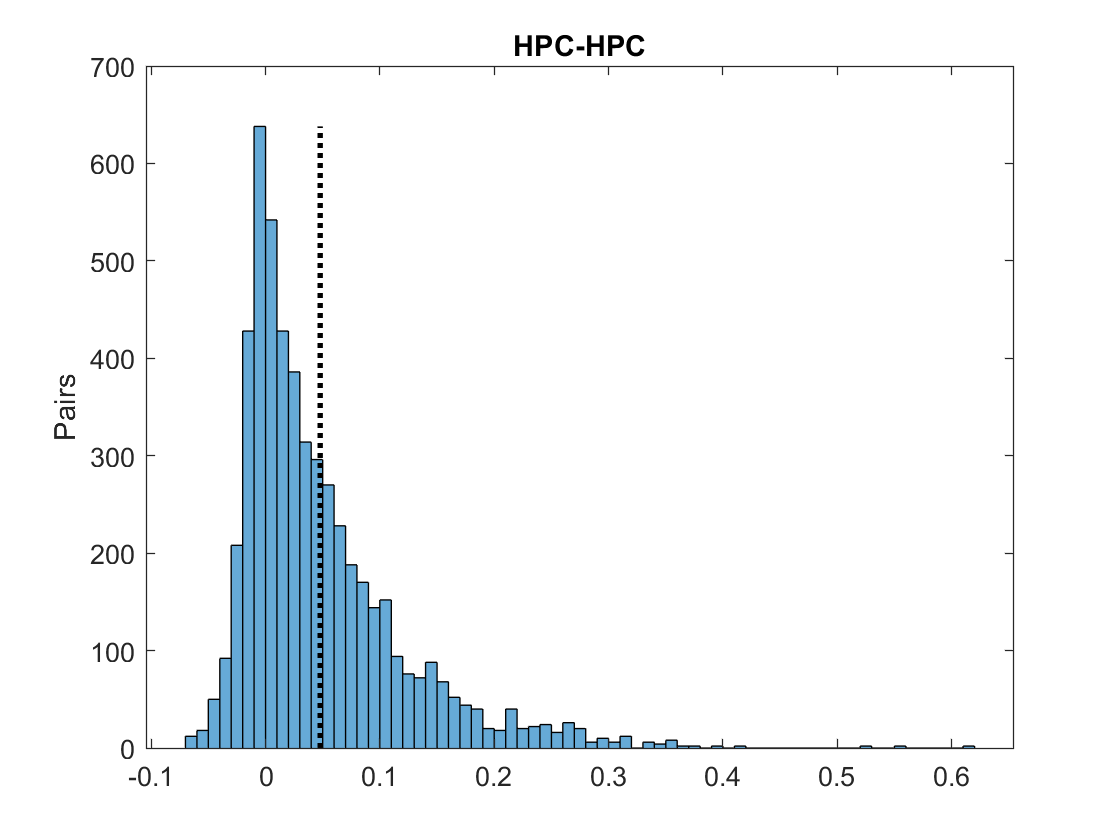

mean_hhcorr = mean(all_pairs_within_hpc(~isnan(all_pairs_within_hpc)));
std_hhcorr = std(all_pairs_within_hpc(~isnan(all_pairs_within_hpc)));

hold on
lineObject=line([mean_hhcorr,mean_hhcorr],[0 max(hist_hh.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black
subplot(2,1,2)
ax2 = nexttile;

hist_hp = histogram(all_pairs_across_regions)
ylabel("Pairs")
title ("HPC-PFC")

hist_hp =   Histogram with properties:

             Data: [1×5904 double]
           Values: [4 14 22 42 150 510 776 666 560 414 386 300 258 284 182 194 116 132 76 52 48 36 22 22 24 14 6 0 2 6 4 4 10 8 4 0 0 2 0 2 4 6 2 4 0 0 2 2 0 4 2 0 0 0 2 0 0 0 0 0 0 0 0 2]
          NumBins: 64
         BinEdges: [1×65 double]
         BinWidth: 0.0100
        BinLimits: [-0.0700 0.5700]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


mean_hpcorr = mean(all_pairs_across_regions(~isnan(all_pairs_across_regions)));
std_hpcorr = std(all_pairs_across_regions(~isnan(all_pairs_across_regions)));

lineObject=line([mean_hpcorr,mean_hpcorr],[0 max(hist_hp.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black
xlabel("Pairwise correlation")
linkaxes([ax1,ax2],'x');
[h_corrdiff,p_corrdiff] = kstest2(all_pairs_across_regions,all_pairs_within_hpc);

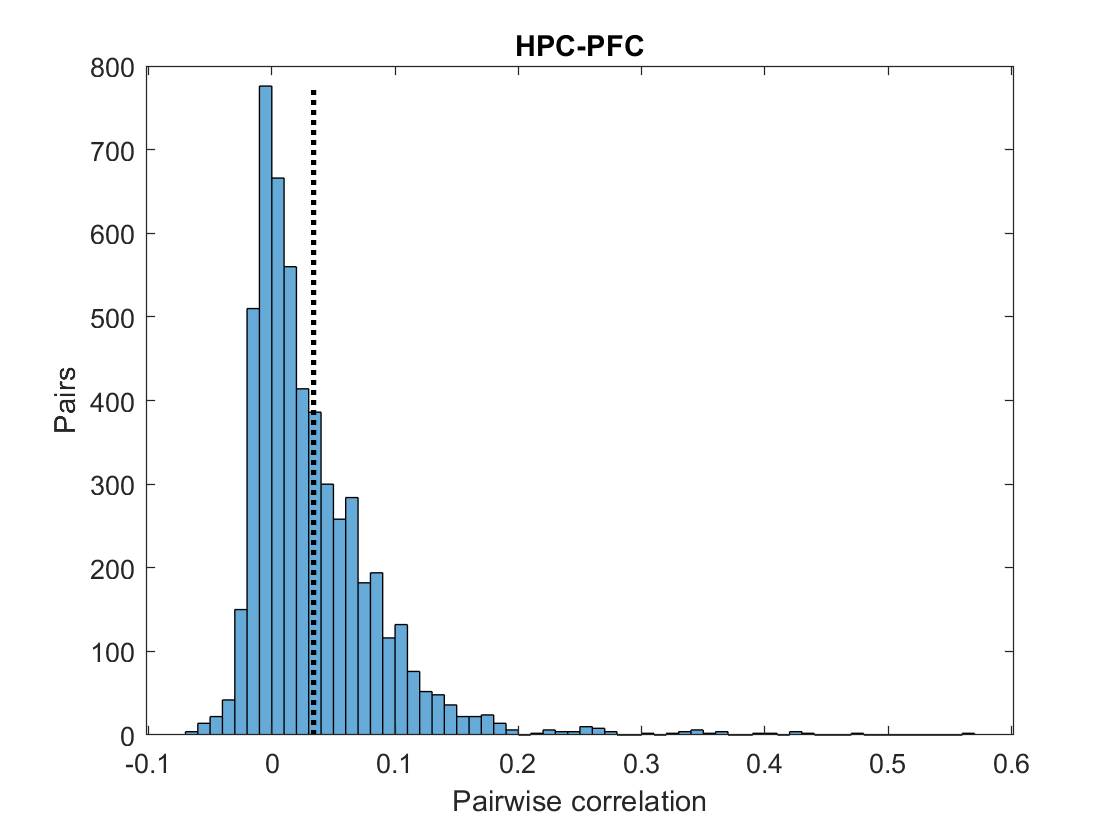

% saving meaningful stats and the corresponding Option fields in a csv

Optiontable = table(struct2array(Option))
Resulttable = table(mean_hhcorr, std_hhcorr, mean_hpcorr, std_hpcorr, h_corrdiff, p_corrdiff)
 
cofiringstats.cofiringRow = [cofiringstats.cofiringRow; table(Optiontable, Resulttable)];

Optiontable = table
        Var1    
    ____________

    [1×7 string]


save('cofiring', 'cofiringstats')

Resulttable = 1×6 table
    mean_hhcorr    std_hhcorr    mean_hpcorr    std_hpcorr    h_corrdiff    p_corrdiff
    ___________    __________    ___________    __________    __________    __________

      0.04784       0.071983      0.033958       0.054816       true        1.0657e-21



% print stats
formatSpec1 = "%s: %0.3f±%0.3f";

sprintf(formatSpec1,Patterns(1,1).directionality,mean_hhcorr,std_hhcorr)
sprintf(formatSpec1,Patterns(2,1).directionality,mean_hpcorr,std_hpcorr)

disp(p_corrdiff)


ans = "hpc-hpc: 0.048±0.072"

Average correlation:

HPC-HPC: 0.1413 ± 0.1047

HPC-PFC: 0.0397 ± 0.0509

p < 0.01 for difference between HPC-PFC and HPC-HPC.

*"These weak correlations indicate that only a small fraction of a neuron’s response variability*

*can be explained by another individual neuron"*

#### B: Prediction Performance

predictionstats = load("prediction.mat");

ans = "hpc-pfc: 0.034±0.055"

figure(600), clf
% how well a single neuron can predict stuff

   1.0657e-21



all_single_prediction_hh = [];
all_single_prediction_hp = [];

patternPerformance_pfc = []; % prediction of 
patternPerformance_hpc = [];

for i = 1:nPatterns
    curr_source = (X_source{i})';
    
    for d = 1:2
        curr_target = (X_target{d,i})';
        for k = 1:nSource
            curr_singleB = Patterns(d,i).rankRegress.singlesource_B{k};
            curr_singlesource = curr_source(:,k);
            [singlepattern,~] = plots.calculatePredictionPerformance(curr_singlesource,curr_target,  curr_singleB);
            if d==1
                [all_single_prediction_hh] = [all_single_prediction_hh singlepattern];
            else
                [all_single_prediction_hp] = [all_single_prediction_hp singlepattern];
            end
        end
    end
end

median_singlehh = median(all_single_prediction_hh(~isnan(all_single_prediction_hh)));
temp = all_single_prediction_hp(~isinf(all_single_prediction_hp));
temp = temp(~isnan(temp));
median_singlehp = median(temp);


r_square_hh = [];
r_square_hp = [];

for i = 1:nPatterns
    curr_source = (X_source{i})';
    curr_targethpc = (X_target{1,i})';
    curr_targetpfc = (X_target{2,i})';
    
    curr_B_hpc = Patterns(1,i).rankRegress.B;
    curr_B_pfc = Patterns(2,i).rankRegress.B;
    
    [patternhpc, meanhpc] = plots.calculatePredictionPerformance(curr_source, curr_targethpc, curr_B_hpc);
    [patternpfc, meanpfc] = plots.calculatePredictionPerformance(curr_source, curr_targetpfc, curr_B_pfc);
    
    r_square_hh = [r_square_hh patternhpc];
    r_square_hp = [r_square_hp patternpfc];
    
    patternPerformance_hpc = [patternPerformance_hpc, meanhpc];
    patternPerformance_pfc = [patternPerformance_pfc, meanpfc];
    
end



mean_hh = mean(r_square_hh(~isinf(r_square_hh)));
std_hh  = std(r_square_hh(~isinf(r_square_hh)));

mean_hp = mean(r_square_hp(~isinf(r_square_hp)));
std_hp = std(r_square_hp(~isinf(r_square_hp)));

subplot(2,1,1)
ax1 = nexttile;
hist_hh = histogram(r_square_hh,25)

hist_hh =   Histogram with properties:

             Data: [1×72 double]
           Values: [4 5 5 5 6 8 5 4 7 1 3 2 1 1 3 2 0 0 4 0 0 1 0 0 2]
          NumBins: 25
         BinEdges: [0 0.0167 0.0334 0.0501 0.0668 0.0835 0.1002 0.1169 0.1336 0.1503 0.1670 0.1837 0.2004 0.2171 0.2338 0.2505 0.2672 0.2839 0.3006 0.3173 0.3340 0.3507 0.3674 0.3841 0.4008 0.4175]
         BinWidth: 0.0167
        BinLimits: [0 0.4175]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


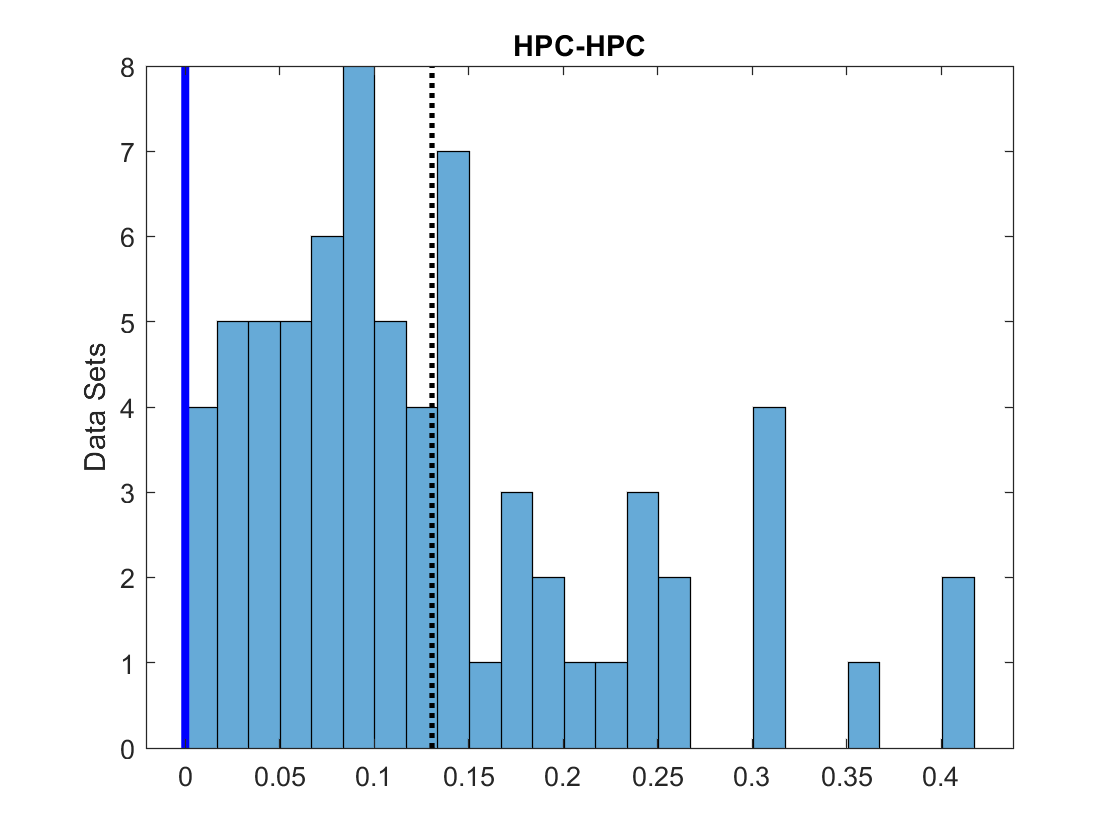

ylabel("Data Sets")
title ("HPC-HPC")
lineObject=line([mean_hh,mean_hh],[0 max(hist_hh.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black
if usingSingleprediction
    lineObject2 = line([median_singlehh,median_singlehh],[0 max(hist_hh.Values)]);
    lineObject2.LineWidth = 3;
    lineObject2.Color = 'blue';
end


subplot(2,1,2)
ax2 = nexttile;
hist_hp = histogram(r_square_hp,25)

hist_hp =   Histogram with properties:

             Data: [1×72 double]
           Values: [29 9 7 5 2 2 1 1 2 2 2 2 0 0 2 0 1 0 0 0 1 0 0 0 1]
          NumBins: 25
         BinEdges: [0 0.0185 0.0370 0.0555 0.0740 0.0925 0.1110 0.1295 0.1480 0.1665 0.1850 0.2035 0.2220 0.2405 0.2590 0.2775 0.2960 0.3145 0.3330 0.3515 0.3700 0.3885 0.4070 0.4255 0.4440 0.4625]
         BinWidth: 0.0185
        BinLimits: [0 0.4625]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


% prediction performance from hpc to pfc cells
ylabel("Data Sets")
title ("HPC-PFC")
xlabel("Performance")
linkaxes([ax1,ax2],'x');

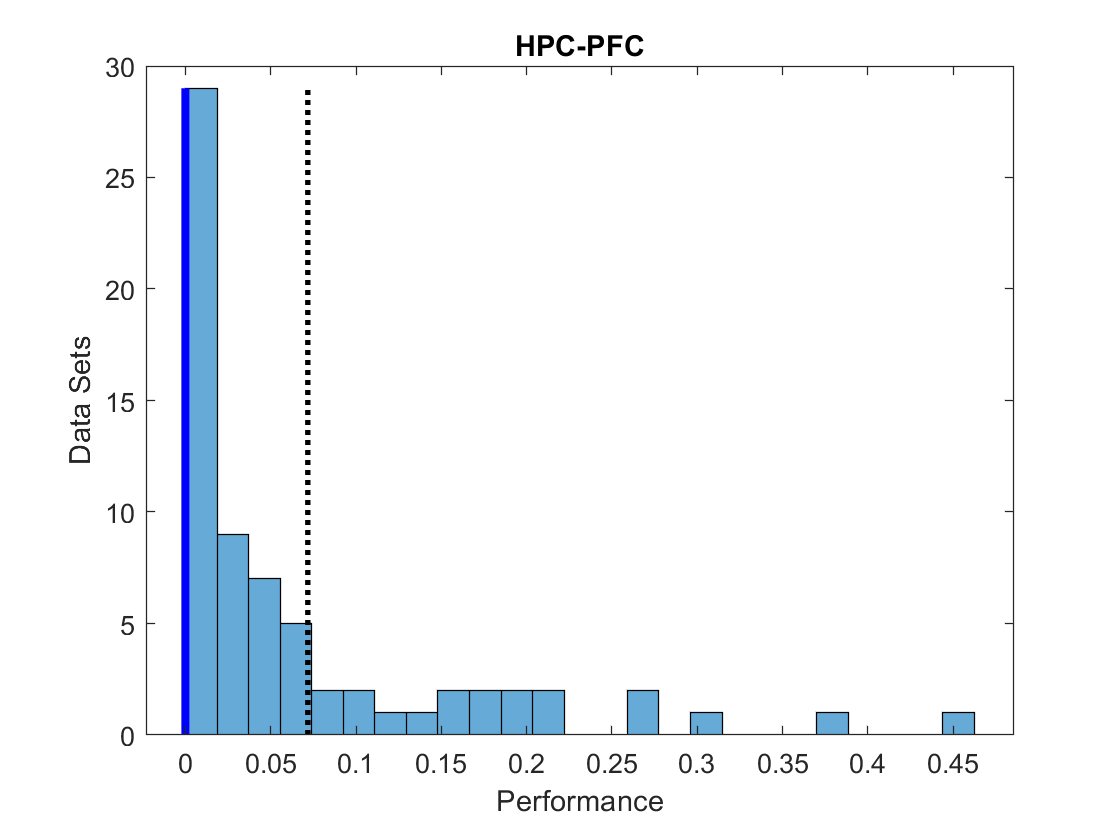

lineObject=line([mean_hp,mean_hp],[0 max(hist_hp.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black
if usingSingleprediction
    lineObject2 = line([median_singlehp,median_singlehp],[0 max(hist_hp.Values)]);
    lineObject2.LineWidth = 3;  % Thicken the line
    lineObject2.Color = 'blue'; % Color it black
end

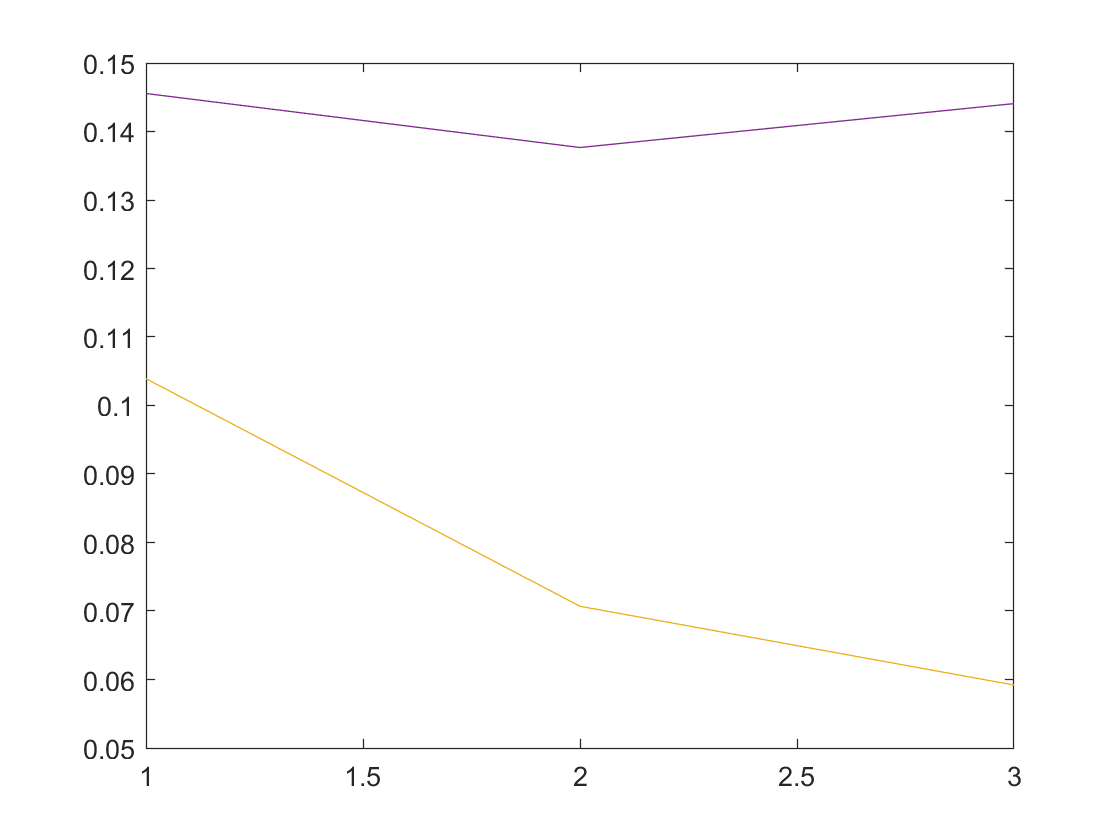

figure(601)
plot(patternPerformance_pfc);
hold on
plot(patternPerformance_hpc);

ax = gca;
ax.XAxis.TickLabelFormat = categorical({'theta','delta','ripple'})

Unrecognized property 'Categories' for class 'matlab.graphics.axis.decorator.NumericRuler'.

legend("pfc","hpc")



% saving meaningful stats and the corresponding Option fields in a csv
Predictiontable  = table(mean_hh, std_hh, mean_hp, std_hp)

Predictiontable = 1×4 table
    mean_hh     std_hh     mean_hp      std_hp 
    _______    ________    ________    ________

    0.13045    0.097176    0.071716    0.096135


predictionstats.predictionRow = [predictionstats.predictionRow; table(Optiontable, Predictiontable )];
save('prediction','predictionstats');


% print stats
formatSpec1 = "%s: %0.3f±%0.3f";
disp("Prediction Performance on Average")

Prediction Performance on Average


sprintf(formatSpec1,Patterns(1,1).directionality,mean_hh,std_hh)

ans = "hpc-hpc: 0.147±0.096"

sprintf(formatSpec1,Patterns(2,1).directionality,mean_hp,std_hp)

ans = "hpc-pfc: 0.055±0.068"

if usingSingleprediction
    disp('single source prediction median')
    formatSpec2 = "%s: %0.5e";
    sprintf(formatSpec2,Patterns(1,1).directionality,median_singlehh)
    sprintf(formatSpec2,Patterns(1,2).directionality,median_singlehp)

end

ans = "hpc-hpc: -6.72289e-05"

ans = "hpc-hpc: -9.28362e-05"

## Figure 4

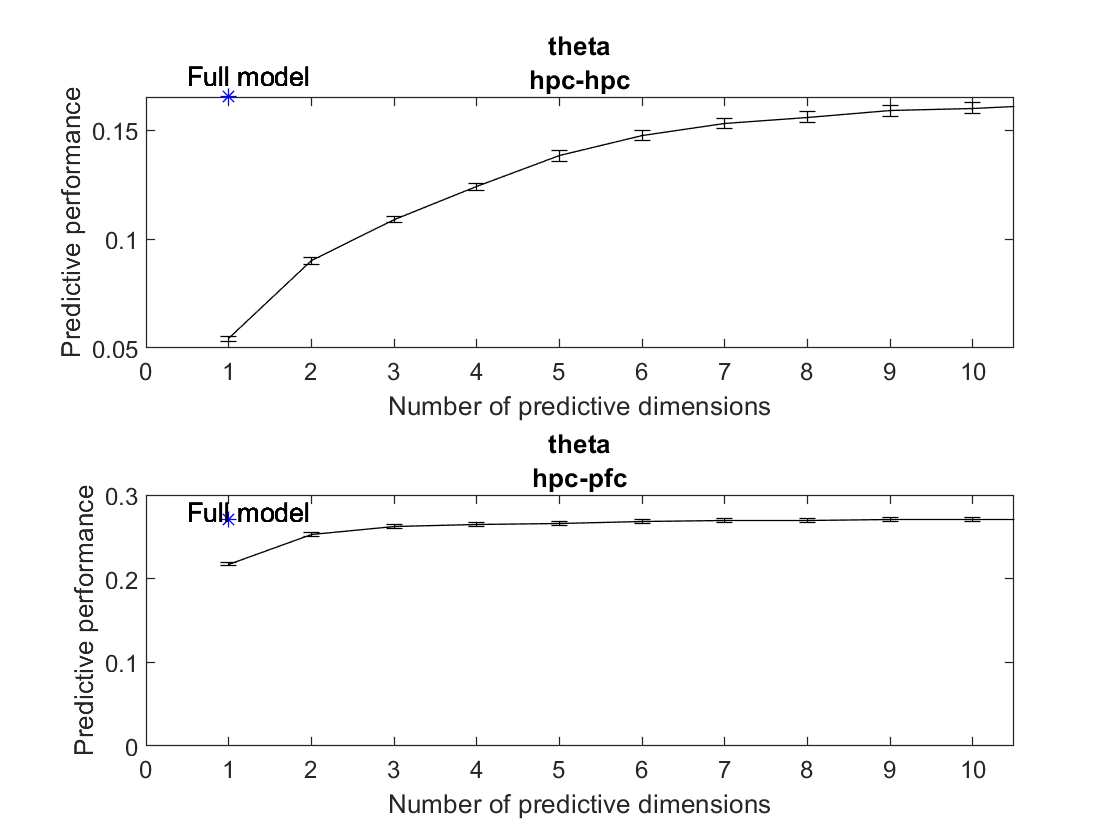

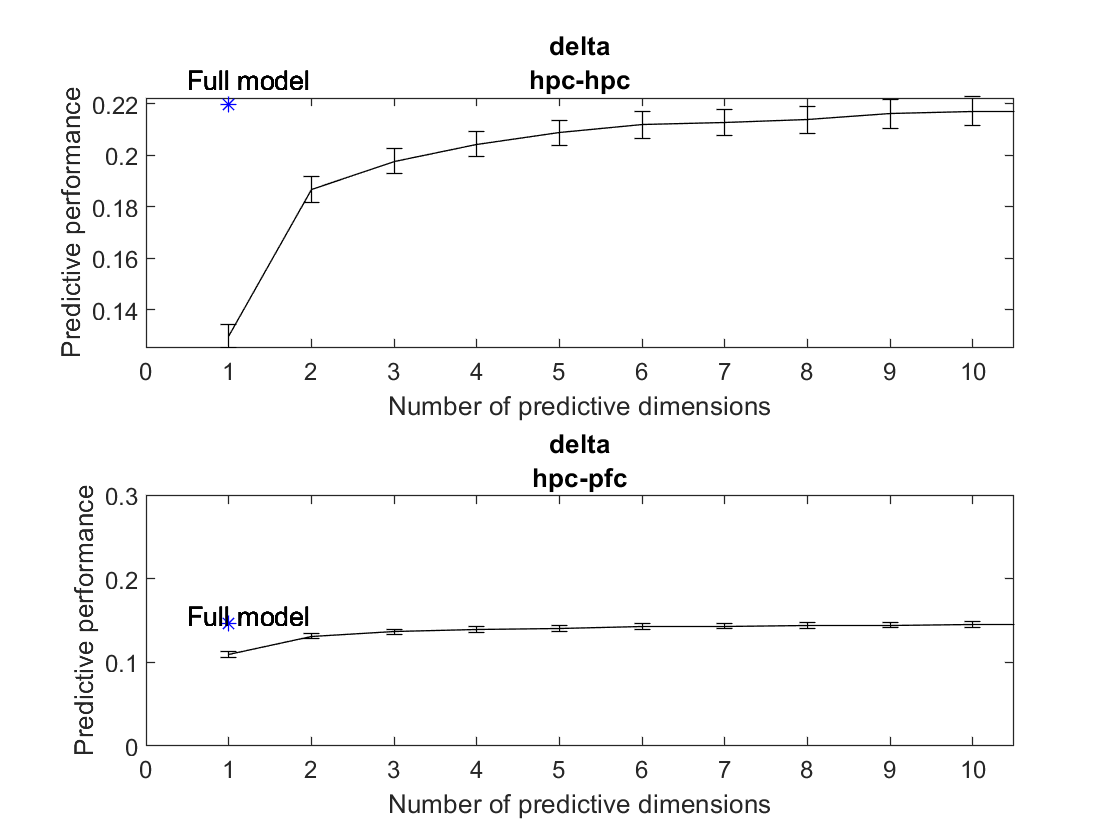

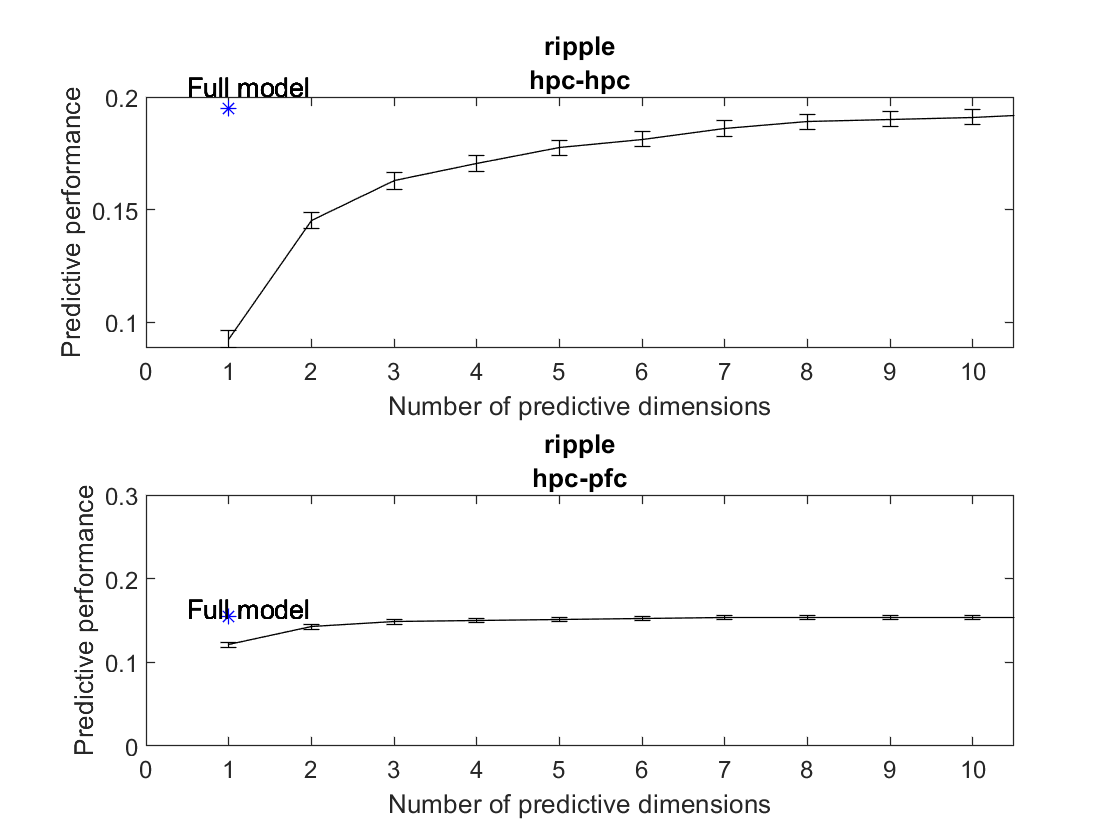

x_hp = 1:nPFCneurons;
for i = 1:nPatterns
    figure(700+i)
    
    for j = 1:2
        subplot(2,1,j)
        curr_cvLoss = Patterns(j,i).rankRegress.cvLoss;
        plots.plotPredictiveDimensions(x_hp,curr_cvLoss);
        title([Patterns(j,i).name Patterns(j,i).directionality])
        xlim([0,10.5])
        
        hold on
        full_model = 1-curr_cvLoss(1,end);
        plot(1, full_model,'b*');
        text(0.5, full_model+0.01, "Full model")
        
    end
    hold on
    ylim([0 0.3])
end

#### 4C

#### How optimal number of predicitive dimensions compare between hpc and pfc (this is gathered over animals)

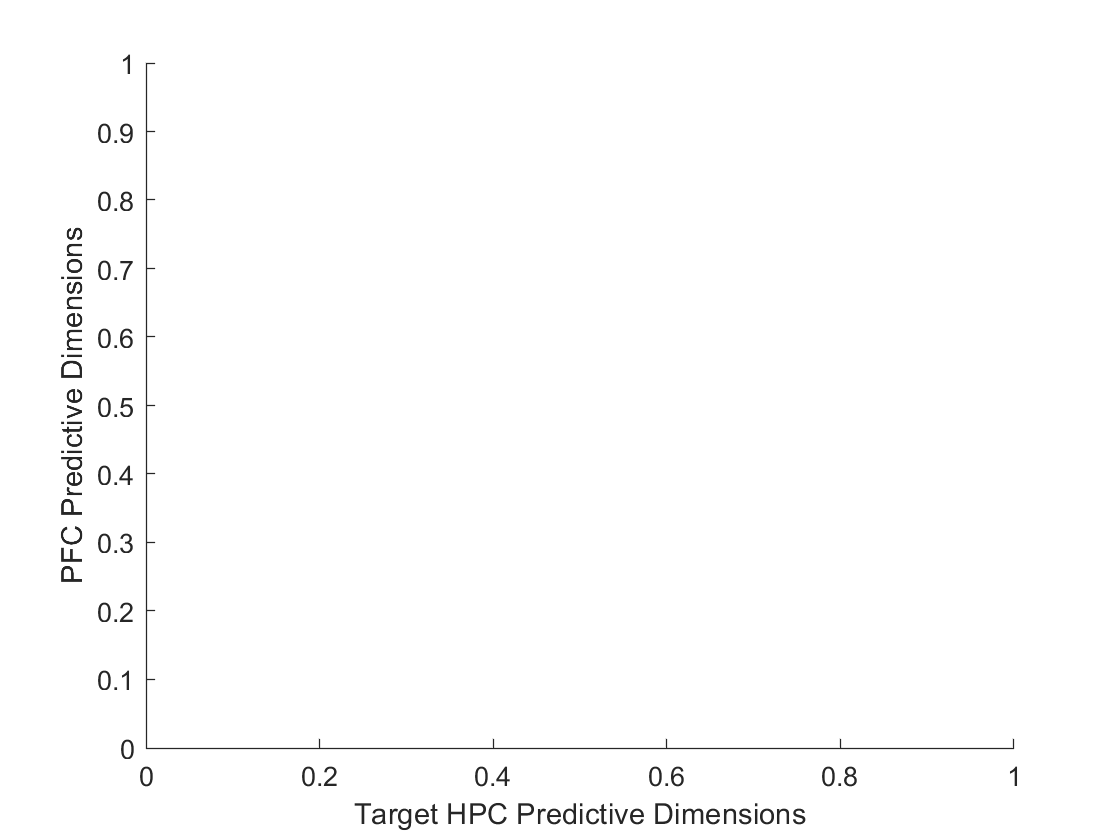

dimensions_hpc = [];
dimensions_pfc = [];
% for animal in animal tables, retrieve those with same option conditions,
% and do the following

% collect respective dim_pfc and dim_hpc for each pattern, and divide to
% get the ratio.

figure(800)
ylabel("PFC Predictive Dimensions")
xlabel("Target HPC Predictive Dimensions")


for i = 1:nPatterns
    
    
end